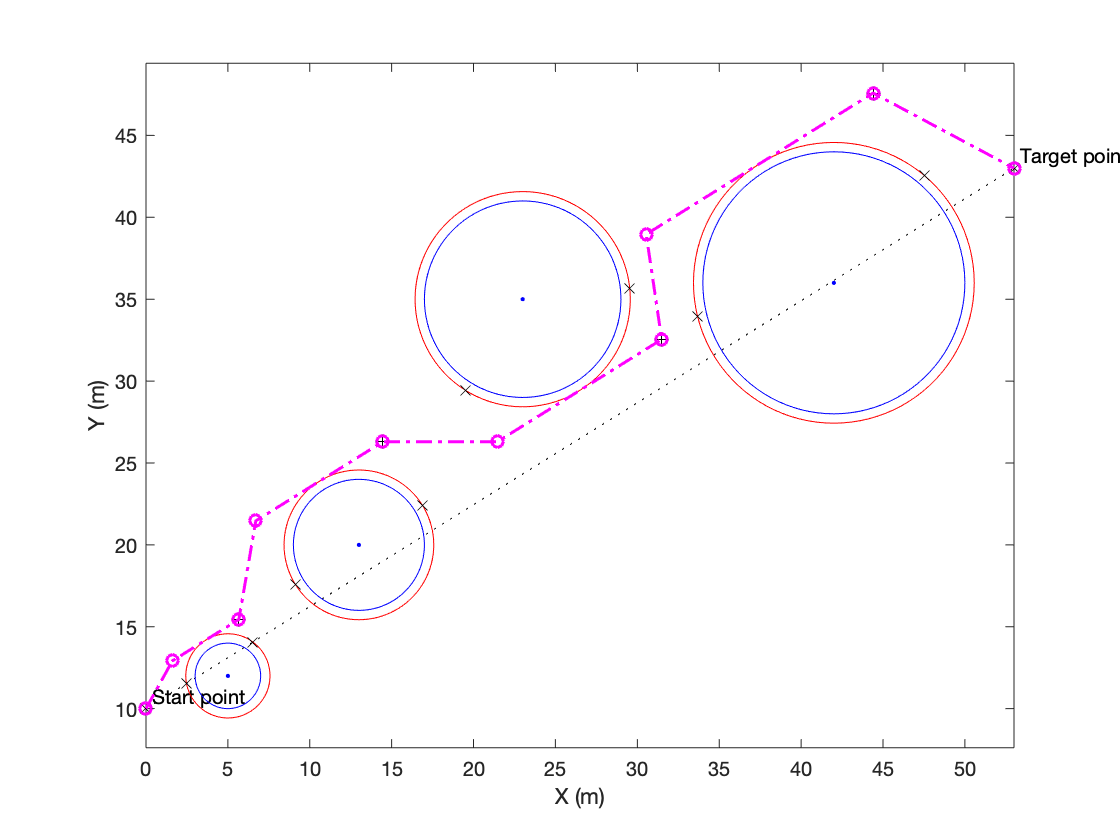

%%                 - Autonomous USV Path Planning Algorithm -                  %%
%    This code uses an algorithm based on the projection collision avoidance    %
%      method to find a path from the start point to the target point           %
%        keeping the tangential to the obstacles segments parallel              %
%                 to the straight line connecting S and T                       %
%                                                                               %
%                Written by Dimitrios Stergianelis on August 2018               %
%                                                                               %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
% Clean the workspace and close the open figures
clear
clc
close all
tic;
 
%% Parameters - Setting up the problem
 
% Start point S (XS, YS)
XS = 0;
YS = 10;
 
% Target point T (XT, YT)
XT = 53;
YT = 43;
 
% Obstacle representation: circle with centre at (XO, YO) and radius RO
XO = [5, 13, 23, 42];
YO = [12, 20, 35, 36];
RO = [2, 4, 6, 8];
 
% Safety radius RB
% Was set equal to the radius of the vessel region (RV), for the simulations
RB = 0.571;
 
% Number of obstacles N
N = length(XO);
 
%% Plotting basic features
 
% Add description to data points S and T
txt1 = ' Start point';
text(XS,YS,txt1,'VerticalAlignment','bottom')
hold on; axis equal; box on; xlabel('X (m)'); ylabel('Y (m)');
 
txt2 = ' Target point';
text(XT,YT,txt2,'VerticalAlignment','bottom')
 
% % Update position vector
X_pos = [XS];
Y_pos = [YS];
 
% Plot straight line from S to T with black dotted line
plot([XS XT], [YS YT], ':xk')
 
% Calculate the length of the straight line from S to T
Ls = sqrt((XT - XS)^2 + (YT - YS)^2);
 
 
for i=1:N
    % Calculate the determinant radius
    RD(i) = RO(i) + RB;
    % Plot centre of obstacle circle
    plot(XO(i), YO(i), '.b')
    % Plot the circle with RO radius
    plot_circle(XO(i), YO(i), RO(i), 'b');
    % Plot the circle with RD radius
    plot_circle(XO(i), YO(i), RD(i), 'r');
end
 
%% Core calculations
 
% Find the straight-line equation (Y = a*X+b) connecting the start and target point
a = (YS - YT)/(XS - XT);
b = (XS*YT - XT*YS)/(XS - XT);
 
% Setting the order of the obstacles
for i=1:N
    % The coordinates of the first point in the initial system
    XFI(i)=XO(i) - RD(i)*cos(a);
    YFI(i)=YO(i) - RD(i)*sin(a);
    % The coordinates of the first point in the rotated system
    XFR(i)=XFI(i)*cos(a) + YFI(i)*sin(a);
    YFR(i)=YFI(i)*cos(a) - XFI(i)*sin(a);
end
 
% Creating a matrix to know the order of the obstacles, moving parallel to
% the S to T straight-line
[B,j]=sort(XFR);
 
for i=1:N
    % Check if boat is already inside obstacle region
    if (sqrt((XS - XO(j(i)))^2 + (YS - YO(j(i)))^2) < RD(j(i))) || (sqrt((XT - XO(j(i)))^2 + (YT - YO(j(i)))^2) < RD(j(i)))
        error('Start/Target point(s) inside obstacle region')
    end
    
    % Check if path is unobstructed by obstacle by checking if both S and T points
    % are in the same quadrant with reference to the centre of the obstacle circle
    path_unobstructed = (sign(XS - XO(j(i))) == sign(XT - XO(j(i)))) && (sign(YS - YO(j(i))) == sign(YT - YO(j(i))));
end
 
%% Basic calculations for the obstacles
 
for i=1:N % N is the number of the obstacle
    
    % I need to know the straight line equation that the vessel is following
    % Initially was Y=a*X+b connecting the S and T points.
    % After every run the straight line equation update itself.
    % The new b is calculated in the end of the loop
    % No need to calculate a new 'a' because all the lines are parallel to the
    % initial one.
    
    % Find the cross points between the straight line and the (i) circle
    A(i) = (a^2 + 1);
    B(i) = 2*(a*b - a*YO(j(i)) - XO(j(i)));
    C(i) = (YO(j(i))^2 - RD(j(i))^2 + XO(j(i))^2 - 2*b*YO(j(i)) + b^2);
    
    % Determinant calculation
    D(j(i)) = B(i)^2 - 4*A(i)*C(i);
    
    % If D(j(i))<=0 then solve straight line equation with the next (i+1)circle
    if (D(j(i))<=0)
        disp('Obstacle skipped')
        continue
    end
    
    % If D(j(i))>0 then two solutions
    % The cross points (X1,Y1) & (X2,Y2)
    X1(i) = (-B(i) + sqrt(B(i)^2 - 4*A(i)*C(i)))/(2*A(i));
    X2(i) = (-B(i) - sqrt(B(i)^2 - 4*A(i)*C(i)))/(2*A(i));
    Y1(i) = a*X1(i) + b;
    Y2(i) = a*X2(i) + b;
    
    % % Plot the cross points
    plot(X1(i), Y1(i), 'xk')
    plot(X2(i), Y2(i), 'xk')
    
    % Find the line equation (Y = av*X + bv) which is vertical to the initial one and is crossing from the centre of the (i) circle
    av(i) = -1/a;
    bv(i) = (a*YO(j(i)) + XO(j(i)))/a;
    
    % Find the cross point (XC, YC) of the two lines. Solve the system (Y = a*X + b) and (Y = av*X + bv)
    XC(i) = (bv(i) - b)/(a - av(i));
    YC(i) = a*XC(i) + b;
    
    % % Plot some important points
    % plot(XC(i), YC(i), 'or')
    
    % Calculate the distance between the cross points
    LP(i) = sqrt((X1(i) - X2(i))^2 + (Y1(i) - Y2(i))^2);
    
    % Calculate the distance from the centre of the (i) circle to the cross point (XC, YC)
    LR(i) = sqrt((XC(i) - XO(j(i)))^2 + (YC(i) - YO(j(i)))^2);
    
    % Calculate the distance from the cross point to the circumference
    LM(i) = RD(j(i)) - LR(i);
    LN(i) = RD(j(i)) + LR(i);
    
    % Calculate the distances from start point S to cross point
    tmp0 = sqrt((X1(i) - XS)^2 + (Y1(i) - YS)^2);
    tmp1 = sqrt((X2(i) - XS)^2 + (Y2(i) - YS)^2);
    
    % SET the smaller D1 and the bigger D2
    if (tmp0 < tmp1)
        D1 = tmp0;
        D2 = tmp1;
    else
        D1 = tmp1;
        D2 = tmp0;
    end
    
    % Calculate the YCRIT for circle
    YCRIT(i) = a*XO(j(i)) + b;
    
    % If YCRIT>=YO then turn CCW angle f
    if (YCRIT(i) >= YO(j(i)))
        f(i) = atan(LM(i)/D1);
        
        % Calculate the distance between start point and the first manoeuvre point
        L(i) = sqrt(LM(i)^2 + D1^2);
        % Calculate the end points of the first manoeuvre
        Xend1(i) = XS + L(i)*cos(atan(a) + f(i));
        Yend1(i) = YS + L(i)*sin(atan(a) + f(i));
        Xend2(i) = XS + L(i)*cos(atan(a) + f(i)) + LP(i)*cos(atan(a));
        Yend2(i) = YS + L(i)*sin(atan(a) + f(i)) + LP(i)*sin(atan(a));
        
        % Plot each manoeuvre end point
        plot(Xend2(i),Yend2(i),'+r')
        
        % Check the maximum allowable turn angle
        at2(i) = -(XO(j(i))*YO(j(i)) - XO(j(i))*Yend2(i) - Xend2(i)*YO(j(i)) + Xend2(i)*Yend2(i) + RD(j(i))*(- RD(j(i))^2 + XO(j(i))^2 - 2*XO(j(i))*Xend2(i) + Xend2(i)^2 + YO(j(i))^2 - 2*YO(j(i))*Yend2(i) + Yend2(i)^2)^(1/2))/(RD(j(i))^2 - XO(j(i))^2 + 2*XO(j(i))*Xend2(i) - Xend2(i)^2);
        limit(i) = atan(at2(i)) - atan(a);
        
        % Must compare f(i from 2 to 5) with limit (i from 1 to 4)
        if (i > 1)
            if (abs(limit(i-1)) > abs(f(i)))
                %     disp('allow');
            else % limit
                %     disp('do not allow');
                % Calculate the distance between start point and the first manoeuvre point
                L(i) = sqrt(LN(i)^2 + D1^2);
                % Then turn CW angle f
                f(i) = -atan(LN(i)/D1);
            end
        end
        
    else % If YCRIT<YO then turn CW angle f
        f(i) = -atan(LM(i)/D1);
        % Calculate the distance between start point and the first manoeuvre point
        L(i) = sqrt(LM(i)^2 + D1^2);
        % Calculate the end points of the first manoeuvre
        Xend1(i) = XS + L(i)*cos(atan(a) + f(i));
        Yend1(i) = YS + L(i)*sin(atan(a) + f(i));
        Xend2(i) = XS + L(i)*cos(atan(a) + f(i)) + LP(i)*cos(atan(a));
        Yend2(i) = YS + L(i)*sin(atan(a) + f(i)) + LP(i)*sin(atan(a));
        
        % Plot each manoeuvre end point
        plot(Xend2(i),Yend2(i),'+r')
        
        % Check the maximum allowable turn angle
        at1(i) = (XO(j(i))*Yend2(i) - XO(j(i))*YO(j(i)) + Xend2(i)*YO(j(i)) - Xend2(i)*Yend2(i) + RD(j(i))*(- RD(j(i))^2 + XO(j(i))^2 - 2*XO(j(i))*Xend2(i) + Xend2(i)^2 + YO(j(i))^2 - 2*YO(j(i))*Yend2(i) + Yend2(i)^2)^(1/2))/(RD(j(i))^2 - XO(j(i))^2 + 2*XO(j(i))*Xend2(i) - Xend2(i)^2);
        limit(i) = pi + atan(at1(i)) - atan(a);
        
        if (i > 1)
            if (abs(limit(i-1)) > abs(f(i)))
                %     disp('allow');
            else % limit
                %     disp('do not allow');
                % Calculate the distance between start point and the first manoeuvre point
                L(i) = sqrt(LN(i)^2 + D1^2);
                % Then turn CCW angle f
                f(i) = atan(LN(i)/D1);
            end
        end
        
    end
    
    %% Updates
    
    % Update position vector - side section
    X_pos = [X_pos, (XS + L(i)*cos(atan(a) + f(i)))];
    Y_pos = [Y_pos, (YS + L(i)*sin(atan(a) + f(i)))];
    
    % Update position vector - parallel section
    X_pos = [X_pos, (XS + L(i)*cos(atan(a) + f(i)) + LP(i)*cos(atan(a)))];
    Y_pos = [Y_pos, (YS + L(i)*sin(atan(a) + f(i)) + LP(i)*sin(atan(a)))];
    
    % Upadate XS YS and b for the next repetition
    XS = XS + L(i)*cos(atan(a) + f(i)) + LP(i)*cos(atan(a));
    YS = YS + L(i)*sin(atan(a) + f(i)) + LP(i)*sin(atan(a));
    b = b + sign(YCRIT(i) - YO(j(i)))*LM(i)/cos(atan(a));
    
    % Maybe I need this b
    %    b = b - sign(YCRIT(i)+Y(j(i)))*LM(i)/cos(a);
    
    % Plot the end points of each loop
    % By bringing the tangential to each circle from these points the maximum allowable turn angle will be determined
    plot(XS,YS,'+k')
    
end
 
% For the last segment of the trajectory update position vector
X_pos = [X_pos, XT];
Y_pos = [Y_pos, YT];
 
% Plot final part of the path with magenta dash-dot line
plot(X_pos, Y_pos, '-.om', 'LineWidth', 1.5)

 
% Display straight-line length
disp(['Straight-line length: ' num2str(Ls)])

Straight-line length: 62.434


 
% Total number of line segments
S = size(X_pos,2)-1;
 
% Display the number of line segments
disp(['Number of line-segments: ' num2str(S)])

Number of line-segments: 9


 
% Find the length of each segment
for z=1:S
    L(z) = sqrt((X_pos(z + 1) - X_pos(z))^2 + (Y_pos(z + 1) - Y_pos(z))^2);
end
 
% Find the total length
TL = sum(L (1:S));
disp(['Trajectory length: ' num2str(TL)])

Trajectory length: 74.7314



toc

Elapsed time is 0.384409 seconds.
